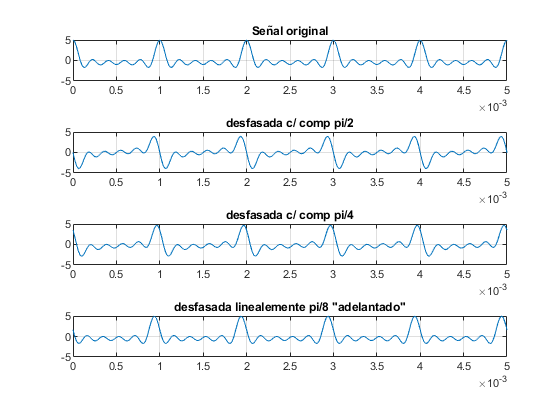

% Generamos una señal compuesta

f1=1e3; fs=48e3;
t= 0:(1/fs):0.01;
y=0*t;
for n=(1:5)
    y=y+cos(2*pi*n*f1*t);
end

% Desfasamos a cada componente pi/2

y2=0*t;
for n=(1:5)
    y2=y2+cos(2*pi*n*f1*t+pi/2);
end

% Desfasamos pi/4

y3=0*t;
for n=(1:5)
    y3=y3+cos(2*pi*n*f1*t+pi/4);
end


% Desfasamos proporcionalemte pi/8 (adelantada)

y4=0*t;
for n=(1:5)
    y4=y4+cos(2*pi*n*f1*t+n*pi/8);
end

subplot(4,1,1)
plot(t,y);
grid on;
axis([0 5e-3 -5 5])

subplot(4,1,2);
plot(t,y2);
grid on;
axis([0 5e-3 -5 5])

subplot(4,1,3);
plot(t,y3);
grid on;
axis([0 5e-3 -5 5])

subplot(4,1,4);
plot(t,y4);
grid on;
axis([0 5e-3 -5 5])

subplot(4,1,1)
title('Señal original')
subplot(4,1,2)
title('desfasada c/ comp pi/2');
subplot(4,1,3)
title('desfasada c/ comp pi/4');
subplot(4,1,4)
title('desfasada linealemente pi/8 "adelantado"');

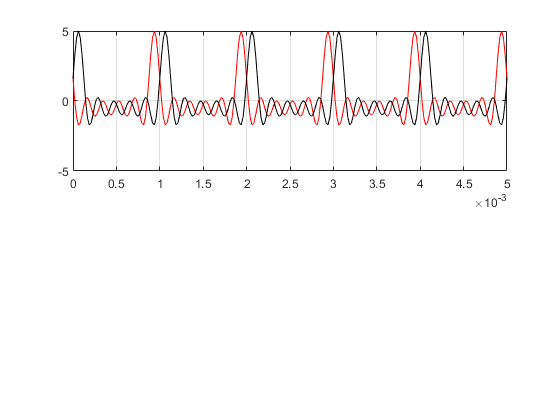

% Desfasamos linealmente pi/8 atrasado
y5=0*t;
for n=(1:5)
    y5=y5+cos(2*pi*n*f1*t-n*pi/8);
end

f=(0:length(t)-1)/length(t)*fs;

clf
subplot(2,1,1)
plot(t,y4,'r',t,y5,'k')
grid on
axis([0 5e-3 -5 5])